# Duffing Oscillator

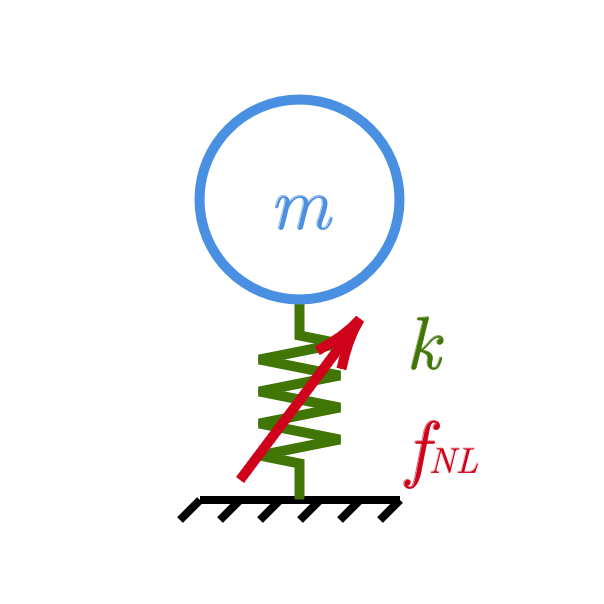

## Initialize

Include the function folder.

addpath(genpath(fullfile('..', 'LSM-opt-functions')))

## Settings

Define the system arguments, i.e., the type of the system under optimization.

sysArgs.systemType = @SystemDuffing;

Define the LSM arguments, i.e., the target dof of the system and the LSM expansion order.

lsmArgs.iDof = 1;
lsmArgs.order = 7;

## Optimization problem

The objective function and the nonlinear constraints are defined in the `fun` and `nonlcon` functions in this folder. 

Define the target points as frequency - amplitude pairs.

optArgs.omegaTarget = [2, 1.9, 2];
optArgs.zTarget = [0, 1.5, 2];

Specify if the frequency - amplitude pairs are treated as equality constraint (0), upper inequality constraint (1), or lower inequality constraint (-1).

optArgs.coeffTarget = [0, 0, 0];

Define the initial conditions for the design variables.

x0 = [4, 30, 0.2, 0.2];

Define the lower and upper bounds for the design variables.

xl = [1, 10, 0.1, 0.1];
xu = [10, 100, 5, 5];

Define the linear equality and inequality constraints (if any).

A = []; b = [];
Aeq = []; beq = [];

## Optimizer options

In this work, `fmincon` is used to solve the nonlinear optimization problem.

Define below the required options

options = optimoptions('fmincon', 'Display', 'iter');
options.Algorithm = "interior-point";
options.EnableFeasibilityMode = true;
options.SpecifyObjectiveGradient = true;
options.SpecifyConstraintGradient = true;

## Solve the optimization problem

Solve the optimization problem.

tStart = tic;
[x, fval] = fmincon(@(x) fun(x), x0, A, b, Aeq, beq, xl, xu, @(x) nonlcon(x, sysArgs, lsmArgs, optArgs), options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.000000e-02    8.682e-01    2.585e-03
    1       2    1.293417e+00    7.393e-01    3.617e+01    4.789e+00
    2       3    1.337149e+00    7.382e-01    3.668e+01    2.724e-02
    3       4    5.341422e+00    3.796e-01    8.128e+02    1.968e+01
    4       6    5.244254e+00    2.221e-01    1.511e+03    9.753e-01
    5       7    4.744145e+00    5.716e-02    1.458e+03    2.354e+00
    6       9    4.746805e+00    3.018e-02    1.868e+03    5.474e-01
    7      10    4.716461e+00    4.951e-03    2.224e+03    7.850e-01
    8      11    4.301146e+00    1.545e-04    1.254e+03    6.109e-01
    9      12    3.909994e+00    8.260e-06    1.498e+02    7.043e-01
   10      13    2.931730e+00    1.314e-06    1.137e+02    1.926e+00
   11      14    2.250028e+00    9.503e-07    6.121e+01    1.542e+00
   12      15    2.439425e+00    3.437e-08    2

tElapsed = toc(tStart);
disp(['Elapsed time is ', num2str(tElapsed, '%.2f'), ' seconds.'])

Elapsed time is 2.50 seconds.


## Post processing

Build the system and perform the eigenvalue analysis

sys = feval(sysArgs.systemType, x, sysArgs);
sys = sys.modal_analysis();

Identify the master mode. In this case, it's the first one.

modeIndex = 1;

sys.omega0 = sys.omega(modeIndex);
sys.phi0 = sys.phi(:, modeIndex);
sys = sys.state_space_modal_analysis();

Build the LSM.

lsm = LSM(sys, lsmArgs.order);
lsm = lsm.compute_manifold();

Compute the backbone points.

rhoTarget = lsm.solve_rho(optArgs.zTarget, lsmArgs.iDof);
rho = linspace(0, max(rhoTarget), 51);
z = lsm.compute_z(rho, lsmArgs.iDof);
omega = lsm.compute_omega(rho);

Plot the backbone curve with the target points.

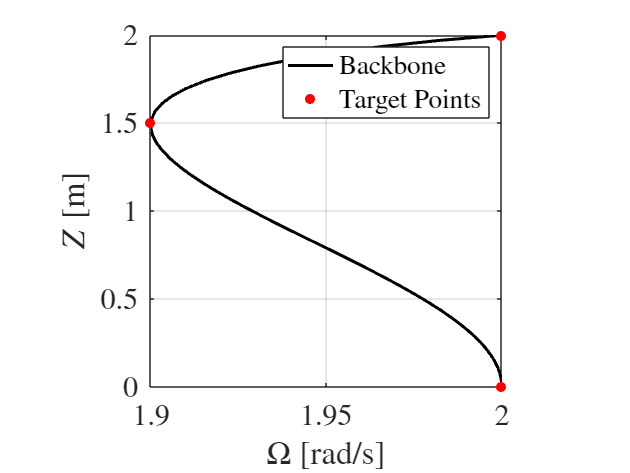

figure();
plot_backbone(omega, z, optArgs.omegaTarget, optArgs.zTarget);